# Call and Provide ROS Services

ROS supports two main communication mechanisms: topics and services. Topics have publishers and subscribers and are used for sending and receiving messages (see [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b)). *Services*, on the other hand, implement a tighter coupling by allowing request-response communication. A *service client* sends a request message to a *service server* and waits for a response. The server will use the data in the request to construct a response message and sends it back to the client. Each service has a type that determines the structure of the request and response messages. Services also have a name that is unique in the ROS network.

This service communication has the following characteristics:

- A service request (or service call) is used for one-to-one communication. A single node will initiate the request and only one node will receive the request and send back a response.

- A service client and a service server are tightly coupled when a service call is executed. The server needs to exist at the time of the service call and once the request is sent, the client will block until a response is received.

The concept of services is illustrated in the following image:

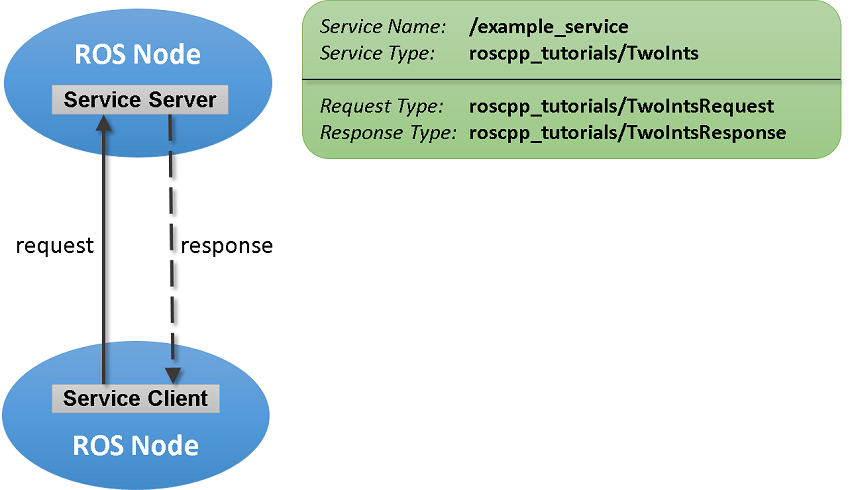

This example shows you how to set up service servers to advertise a service to the ROS network. In addition, you will learn how to use service clients to call the server and receive a response.

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a),  [Connect to a ROS Network](docid:ros_ug.mw_d625a603-7f37-4925-9470-2de734937434),  [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b)

## Create Service Server

Before examining service concepts, start the ROS master in MATLAB® and the sample ROS network. `exampleHelperROSCreateSampleNetwork` will create some service servers to simulate a realistic ROS network.

rosinit

Launching ROS Core...
...Done in 3.16 seconds.
Initializing ROS master on http://192.168.178.1:55438.
Initializing global node /matlab_global_node_55791 with NodeURI http://ah-csalzber:51640/


exampleHelperROSCreateSampleNetwork

Suppose you want to make a simple service server that displays *"A service client is calling"* when you call the service. Create the service using the [`rossvcserver`](docid:ros_ref.bupf5_j_11) command. Specify the service name and the service message type. Also define the callback function as `exampleHelperROSEmptyCallback`. Callback functions for service servers have a very specific signature. For details, see the documentation of [`rossvcserver`](docid:ros_ref.bupf5_j_11).

For faster performance, use services with messages in structure format.

testserver = rossvcserver("/test","std_srvs/Empty",@exampleHelperROSEmptyCallback,"DataFormat","struct")

testserver =   ServiceServer with properties:

      ServiceType: 'std_srvs/Empty'
      ServiceName: '/test'
    NewRequestFcn: @exampleHelperROSEmptyCallback
       DataFormat: 'struct'


You can see your new service, `/test`, when you list all services in the ROS network.

rosservice list

/add
/matlab_global_node_55791/get_loggers
/matlab_global_node_55791/set_logger_level
/node_1/get_loggers
/node_1/set_logger_level
/node_2/get_loggers
/node_2/set_logger_level
/node_3/get_loggers
/node_3/set_logger_level
/reply
/test


You can get more information about your service using [`rosservice`](docid:ros_ref.bupf5_j_7)` info`. The global node is listed as node where the service server is reachable and you also see its `std_srvs/Empty` service type. 

rosservice info /test

Node: /matlab_global_node_55791
URI: rosrpc://ah-csalzber:51639
Type: std_srvs/Empty
Args: MessageType


## Create Service Client

Use service clients to request information from a ROS service server. To create a client, use [`rossvcclient`](docid:ros_ref.bupf5_j_10) with the service name as the argument.

Create a service client for the `/test` service that we just created.

testclient = rossvcclient("/test","DataFormat","struct")

testclient =   ServiceClient with properties:

    ServiceType: 'std_srvs/Empty'
    ServiceName: '/test'
     DataFormat: 'struct'


Create an empty request message for the service. Use the [`rosmessage`](docid:ros_ref.bupf5_j_2) function and pass the client as the first argument. This will create a service request function that has the message type and format that is specified by the service.

testreq = rosmessage(testclient)

testreq = struct with fields:
    MessageType: 'std_srvs/EmptyRequest'


Ensure that the service is connected to the client, waiting for them to connect if necessary.

waitForServer(testclient,"Timeout",3)

When you want to get a response from the server, use the [`call`](docid:ros_ref.buqbgqj) function, which calls the service server and returns a response. The service server you created before will return an empty response. In addition, it will call the `exampleHelperROSEmptyCallback` function and displays the string *"A service client is calling"*. You can also define a `Timeout` parameter, which indicates how long the client should wait for a response.

testresp = call(testclient,testreq,"Timeout",3);

If the call function above fails, it will error. Instead of an error, if you would prefer to react to a call failure using conditionals, return the `status` and `statustext` outputs from the call function. The `status` output indicates if the call succeeded, while `statustext` provides additional information. Similar outputs can be returned from `waitForServer`.

numCallFailures = 0;
[testresp,status,statustext] = call(testclient,testreq,"Timeout",3);
if ~status
    numCallFailures = numCallFailues + 1;
    fprintf("Call failure number %d. Error cause: %s\n",numCallFailures,statustext)
else
    disp(testresp)
end

    MessageType: 'std_srvs/EmptyResponse'



## Create a Service for Adding Two Numbers

Up to now, the service server has not done any meaningful work, but you can use services for computations and data manipulation. Create a service that adds two integers.

There is an existing service type, `roscpp_tutorials/TwoInts`, that we can use for this task. You can inspect the structure of the request and response messages by calling `rosmsg show`. The request contains two integers, `A` and `B`, and the response contains their addition in `Sum`.

rosmsg show roscpp_tutorials/TwoIntsRequest

int64 A
int64 B




rosmsg show roscpp_tutorials/TwoIntsResponse


int64 Sum



Create the service server with this message type and a callback function that calculates the addition. For your convenience, the `exampleHelperROSSumCallback` function already implements this calculation. Specify the function as a callback.

sumserver = rossvcserver("/sum","roscpp_tutorials/TwoInts",@exampleHelperROSSumCallback,"DataFormat","struct")

sumserver =   ServiceServer with properties:

      ServiceType: 'roscpp_tutorials/TwoInts'
      ServiceName: '/sum'
    NewRequestFcn: @exampleHelperROSSumCallback
       DataFormat: 'struct'


To call the service server, you have to create a service client. Note that this client can be created anywhere in the ROS network. For the purposes of this example, we will create a client for the `/sum` service in MATLAB.

sumclient = rossvcclient("/sum","DataFormat","struct")

sumclient =   ServiceClient with properties:

    ServiceType: 'roscpp_tutorials/TwoInts'
    ServiceName: '/sum'
     DataFormat: 'struct'


Create the request message. You can define the two integers, `A` and `B`, which are added together when you use the [`call`](docid:ros_ref.buqbgqj) command.

sumreq = rosmessage(sumclient);
sumreq.A = int64(2);
sumreq.B = int64(1)

sumreq = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsRequest'
              A: 2
              B: 1


The expectation is that the sum of these two numbers will be 3. To call the service, use the following command. The service response message will contain a `Sum` property, which stores the addition of `A` and `B`. Ensure that the service server is available before making a call, and react appropriately if it is not.

if isServerAvailable(sumclient)
    sumresp = call(sumclient,sumreq,"Timeout",3)
else
    error("Service server not available on network")
end

sumresp = struct with fields:
    MessageType: 'roscpp_tutorials/TwoIntsResponse'
            Sum: 3


## Shut Down ROS Network

Remove the sample nodes and service servers from the ROS network.

exampleHelperROSShutDownSampleNetwork

Shut down the ROS master and delete the global node.

rosshutdown

Shutting down global node /matlab_global_node_55791 with NodeURI http://ah-csalzber:51640/
Shutting down ROS master on http://192.168.178.1:55438.


## Next Steps

- Refer to [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36) to explore how ROS messages are represented in MATLAB.

*Copyright 2014-2021 The MathWorks, Inc.*